% Carica un'immagine di esempio in scala di grigi
I = imread('cameraman.tif');  % O usa 'cameraman.tif' per test
I = im2double(I);            % Converti a double per operazioni matematiche

% Parametri del rumore a bande
amplitude = 0.5;        % Intensità del rumore (0-1)
frequency = 50;         % Numero di bande per immagine
[rows, cols] = size(I);

Applica Rumore

[yGrid, ~] = meshgrid(1:cols, 1:rows);
stripe_pattern = amplitude * sin(2 * pi * frequency * yGrid / rows);
I_noisy = I + stripe_pattern;

Normalizzazione

I_noisy = mat2gray(I_noisy);

Mostra immagini

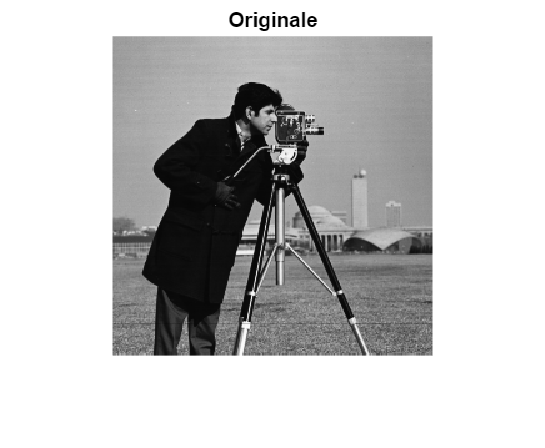

figure;
imshow(I), title('Originale');

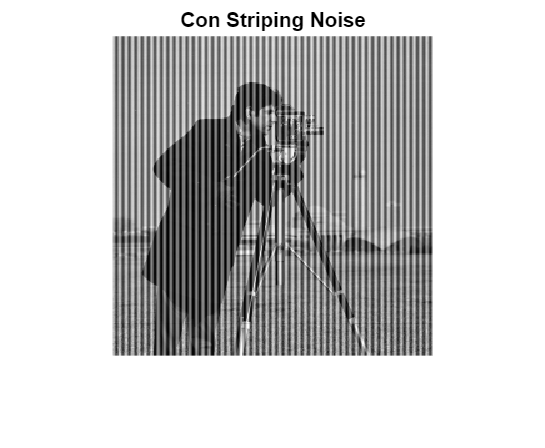

imshow(I_noisy), title('Con Striping Noise');

Filtro highpass

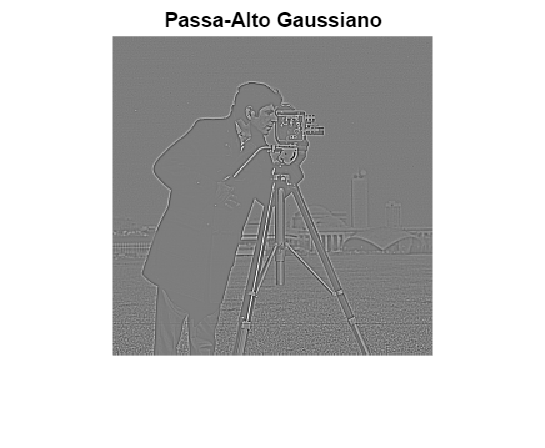

kernel_size = 3;
sigma = 1;

lowpass_gaussian = fspecial('gaussian', kernel_size, sigma);
impulse = zeros(kernel_size);
impulse(ceil(kernel_size/2), ceil(kernel_size/2)) = 1;

highpass_gaussian = impulse - lowpass_gaussian;
% Necessario per generare sharpening
I_highpass = imfilter(I, highpass_gaussian, 'replicate');
imshow(mat2gray(I_highpass)), title('Passa-Alto Gaussiano');

Filtro lowpass

lowpass_kernel = fspecial('average', [3 3]);
I_lowpass = imfilter(I, lowpass_kernel, 'replicate');

Visualizzazione

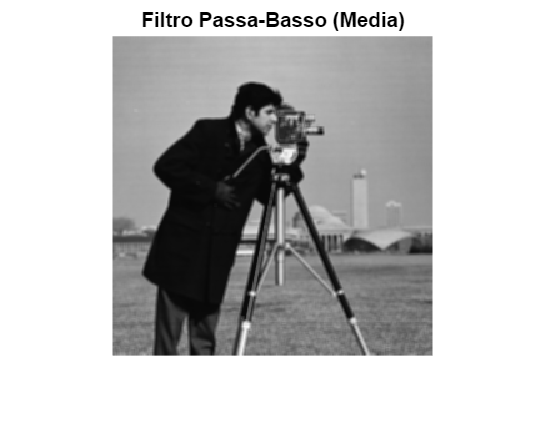

figure;
imshow(I_lowpass), title('Filtro Passa-Basso (Media)');

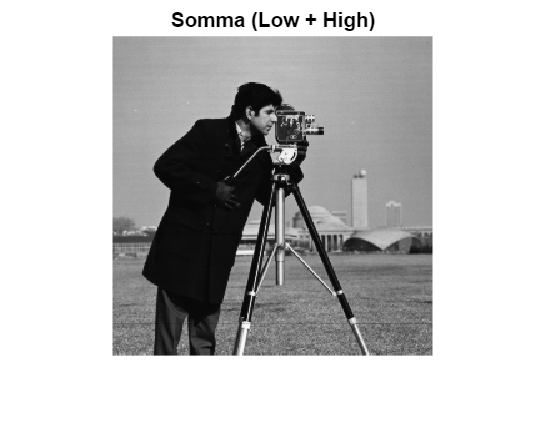

I_sum = I_highpass + I_lowpass;

imshow(I_sum), title('Somma (Low + High)');

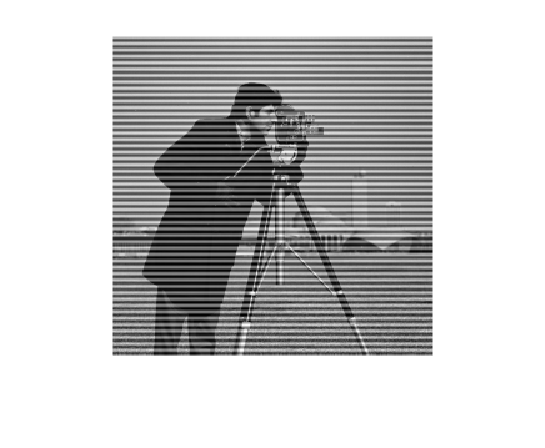

% Parametri del rumore a bande
amplitude = 0.5;        % Intensità del rumore (0-1)
frequency = 50;         % Numero di bande nell'immagine

[rows, cols] = size(I);                     % Dimensioni dell'immagine
[~, yGrid] = meshgrid(1:cols, 1:rows);      % Griglia delle righe (y)

% Crea il pattern di bande orizzontali
stripe_pattern = amplitude * sin(2 * pi * frequency * yGrid / rows);

% Aggiunge il pattern sinusoidale all'immagine
I_noisy = I + stripe_pattern;

% Visualizza (opzionale)
imshow(I_noisy, []);

Filtro highpass

kernel_size = 3;
sigma = 1;

lowpass_gaussian = fspecial('gaussian', kernel_size, sigma);
impulse = zeros(kernel_size);
impulse(ceil(kernel_size/2), ceil(kernel_size/2)) = 1;

highpass_gaussian = impulse - lowpass_gaussian;

I_highpass = imfilter(I, highpass_gaussian, 'replicate');
imshow(mat2gray(I_highpass)), title('Passa-Alto Gaussiano');

Filtro lowpass

lowpass_kernel = fspecial('average', [3 3]);
I_lowpass = imfilter(I, lowpass_kernel, 'replicate');

Visualizzazione

figure;
imshow(I_lowpass), title('Filtro Passa-Basso (Media)');

I_sum = I_highpass + I_lowpass;

imshow(I_sum), title('Somma (Low + High)');